# Servomecanismos Proyecto Académico

*Isa y los Servotasticos*

clc
clear

## Constantes

Se fijan los valores de a y b para que el trébol mida 15 cm de lado y esté sin rotar (esto se usa más adelante, en el modelo del trébol):

a_min = 1.332; % No cambiar 1.332
b_no_rot = 4.71; % No cambiar 4.71

## Config

### Centros

punto_fijo = [0; 0];
centro_trebol = [25; 25];

#### Largo de eslabones 

Con esto, necesitamos que los eslabones en máxima extensión midan al menos:

lado_trebol_max = 15*1.33;
diagonal_max = hypot(lado_trebol_max, lado_trebol_max);
radio_punto_max = hypot(centro_trebol(1), centro_trebol(2)) + diagonal_max/2

radio_punto_max = 49.4621

Se escogen como primera aproximación para la longitud de los eslabones:

largo_eslabon_1 = 20;
largo_eslabon_2 = 30;

El punto máximo al que llegarán estos eslabones es:

radio_alcance_max = largo_eslabon_1+largo_eslabon_2;

Con esto, es posible llegar a todos los puntos de la trayectoria con las longitudes escogidas para los eslabones. Y se deja una tolerancia de [cm]:

radio_tolerancia = radio_alcance_max - radio_punto_max

radio_tolerancia = 0.5379

#### Escala y rotación

escala = 1; % default = 1
rotacion = 0; % default = 0

## Forward Kinematics

l1 = Link('revolute', 'd', 0, 'a', largo_eslabon_1, 'alpha', 0);
l2 = Link('revolute', 'd', 0, 'a', largo_eslabon_2, 'alpha', 0);
robot = SerialLink([l1 l2])

 
robot = 
 
noname:: 2 axis, RR, stdDH, slowRNE                              
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|         20|          0|          0|
|  2|         q2|          0|         30|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


## Inverse Kinematics

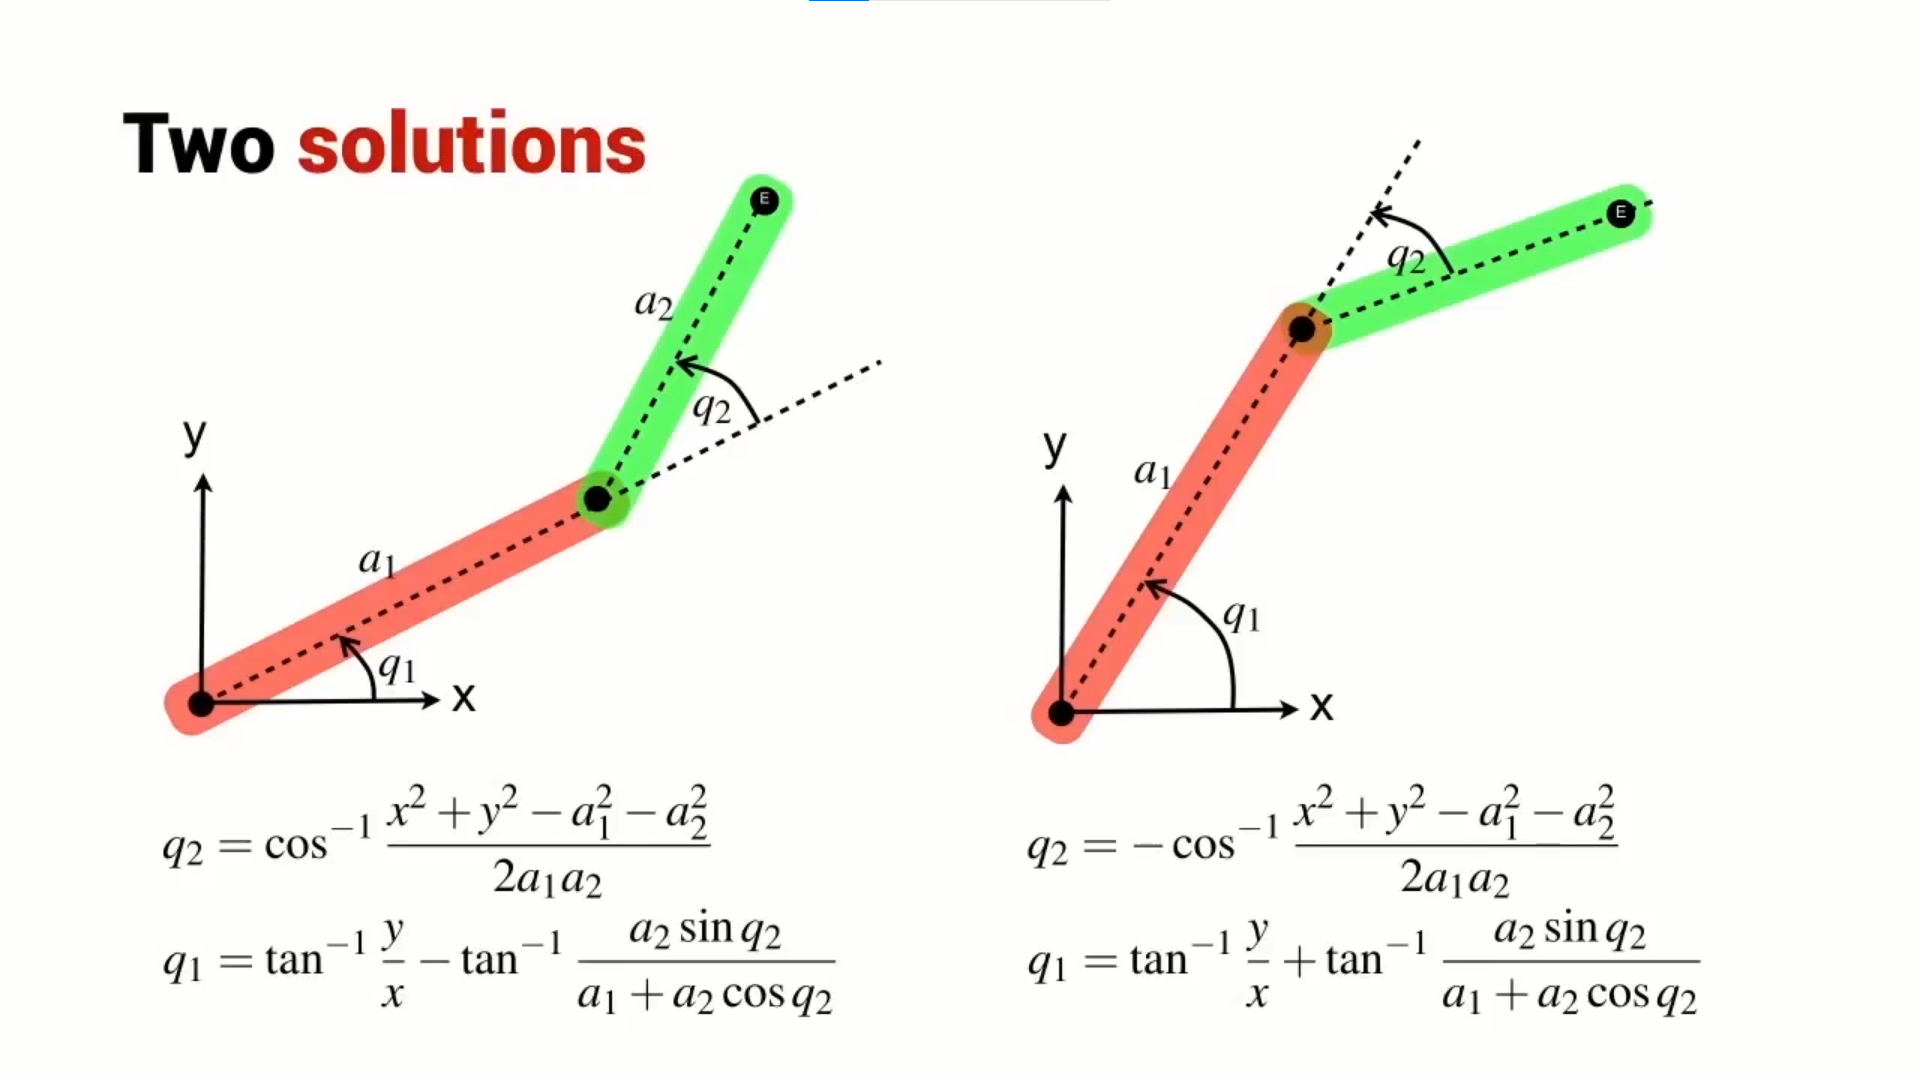

## Trébol

### Definir la trayectoria

syms theta_trebol;
a_trebol = a_min * escala;
b_trebol = b_no_rot + rotacion;
trebol_x(theta_trebol) = (a_trebol*(sin(4*theta_trebol+b_trebol)+6)).*cos(theta_trebol)+centro_trebol(1);
trebol_y(theta_trebol) = (a_trebol*(sin(4*theta_trebol+b_trebol)+6)).*sin(theta_trebol)+centro_trebol(2);

### Discretización de la trayectoria

Si se quiere tener una mejor resolución en la discretización hay que cambiar la variable `intervalo_theta_trebol`. Entre más pequeño el intervalo mejor resolución.

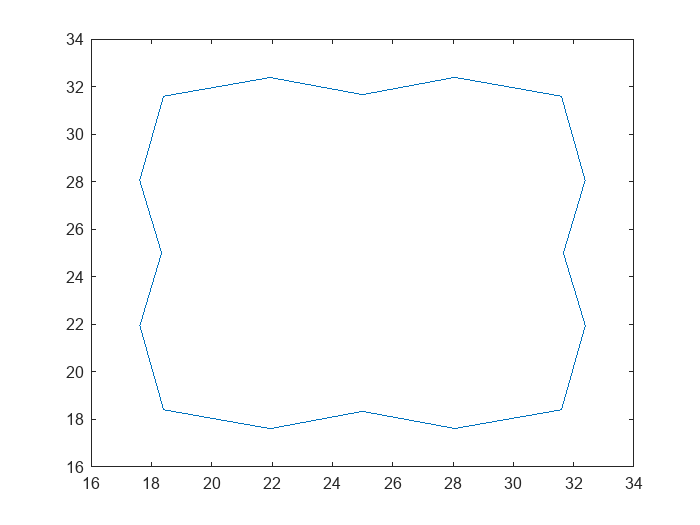

intervalo_theta_trebol = pi/8;
theta_trebol_discreto = 0:intervalo_theta_trebol:2*pi;
trebol_discretizado_x = trebol_x(theta_trebol_discreto);
trebol_discretizado_y = trebol_y(theta_trebol_discreto);
plot(trebol_discretizado_x, trebol_discretizado_y);

## Ángulos para el recorrido

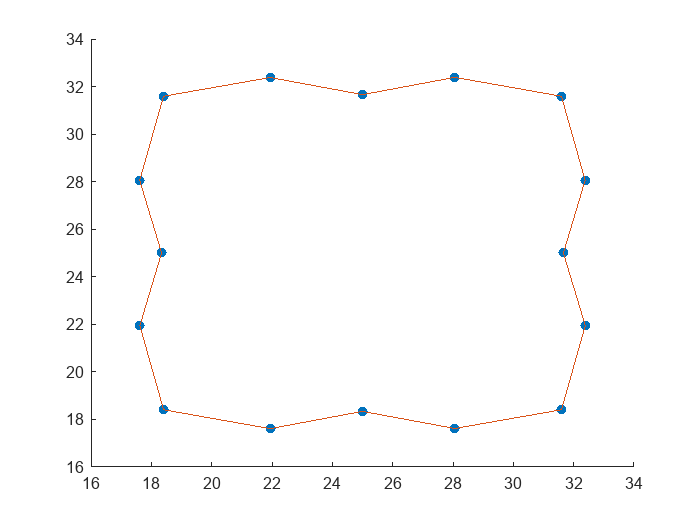

[q1vec, q2vec] = get_angs_multi(largo_eslabon_1, largo_eslabon_2, trebol_discretizado_x, trebol_discretizado_y);
plot_all(trebol_discretizado_x, trebol_discretizado_y, q1vec, q2vec, robot, l1)

## Funciones

Esta función se usa para plotear el brazo.

Esta función se usa para plotear el brazo y el trébol. Se pueden comentar algunas líneas dependiendo de la información que se busca.

function plot_all(trebol_x, trebol_y, q1vec, q2vec, robot, l1)
    % tool
    tx = [];
    ty = [];
    for i = 1:length(q1vec)
        onemth = robot.fkine([q1vec(i) q2vec(i)]);
        tx(end+1) = onemth.t(1);
        ty(end+1) = onemth.t(2);
    end
    scatter(tx, ty, 'filled');
    hold on
    % % codo
    % cx = [];
    % cy = [];
    % for i = 1:length(q1vec)
    %     onemth = l1.A([q1vec(i)]);
    %     cx(end+1) = onemth.t(1);
    %     cy(end+1) = onemth.t(2);
    % end
    % scatter(cx, cy, 'filled');
    % % linea del origen al codo
    % for i = 1:length(cx)
    %     plot([cx(i), 0], [cy(i), 0]);
    % end
    % % linea del codo al tool
    % for i = 1:length(cx)
    %     plot([cx(i), tx(i)], [cy(i), ty(i)]);
    % end
    % trebol
    plot(trebol_x, trebol_y);
    hold off
end

Cinematica inversa

function [q1, q2] = get_angs(a1, a2, x, y)
    q2 = [acos((x^2+y^2-a1^2-a2^2)/(2*a1*a2)); -acos((x^2+y^2-a1^2-a2^2)/(2*a1*a2))];
    q1 = [atan2(y,x)-atan2((a2*sin(q2)),(a1+a2*cos(q2))); atan2(y,x)+atan2((a2*sin(q2)),(a1+a2*cos(q2)))];
    q1 = q1(1:2);
end

Multi inversa

function [q1vec, q2vec] = get_angs_multi(a1, a2, x, y)
    q1vec = [];
    q2vec = [];
    for i = 1:length(x)
        [q1, q2] = get_angs(a1, a2, x(i), y(i));
        q1vec(end+1) = q1(2); % una de las respuestas se está ignorando
        q2vec(end+1) = q2(2);
    end
end